# Sprawozdanie Lisek, Mańka - lab3 Narxnet open i closed loop

clear all
close all
load("doc\lab_3\narxnet_workspace.mat")

Przygotowanie danych, które wykorzystamy do uczenia naszej sieci. 

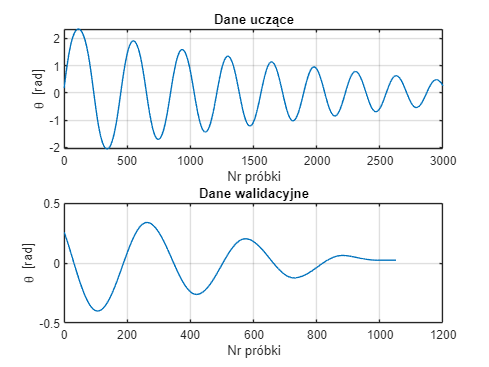

x_begin_sample = 702;
x_end_sample = 4801;

Theta = dane_NN_test2.signals(1).values;
X = Theta(x_begin_sample:x_end_sample)';
X = num2cell(X);

X_train = X(1:3000);
Xnew = X(3000:4050);

figure
subplot(2, 1, 1)
plot(cell2mat(X_train))
xlabel('Nr próbki')
ylabel('\theta [rad]')
grid on
title("Dane uczące")
subplot(2, 1, 2)
plot(cell2mat(Xnew))
xlabel('Nr próbki')
ylabel('\theta [rad]')
grid on
title("Dane walidacyjne")

Następnie szkolimy naszą sieć w pętli otwartej. Z nieznanych nam przyczyn pętla zamknięta działała tylko dla jednej funkcji treningowej  - 'Bayesian Regularization'. Dodatkowo ustawiamy sieć tak, aby wszystkie podane przez nas dane zostały wykorzystane do szkolenia naszej sieci:

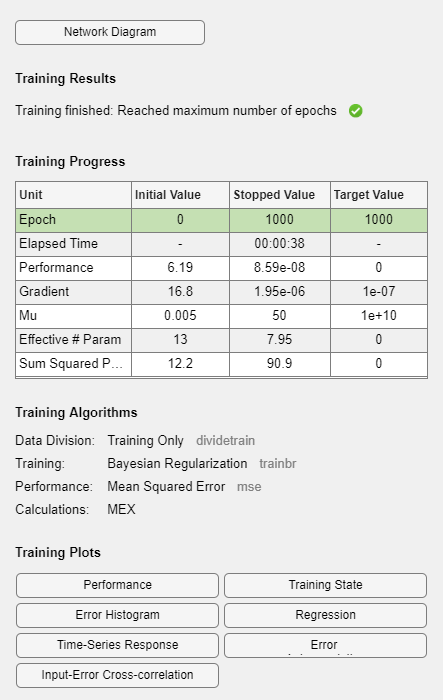

net = narxnet(1:2,1:2,2);
[Xs,Xi,Ai,Ts] = preparets(net,X_train,{},X_train);

net.divideFcn = 'dividetrain';
net.trainFcn = 'trainbr';

net = train(net,Xs,Ts,Xi,Ai);

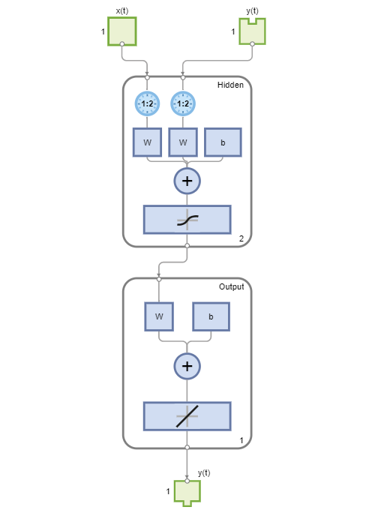

view(net)

[Y,Xf,Af] = net(Xs,Xi,Ai);

Obliczamy błąd naszej sieci oraz wyświetlamy błąd pomiędzy każdą próbką danych:

perf = perform(net,Ts,Y)

perf = 8.5912e-08

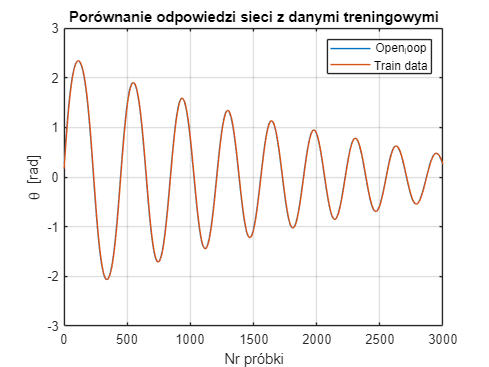

Y_num = cell2mat(Y);

figure();
plot(Y_num)
hold on
plot(cell2mat(X_train))
legend('Open_loop', 'Train data')
xlabel('Nr próbki')
ylabel('\theta [rad]')
title('Porównanie odpowiedzi sieci z danymi treningowymi')
grid on
hold off

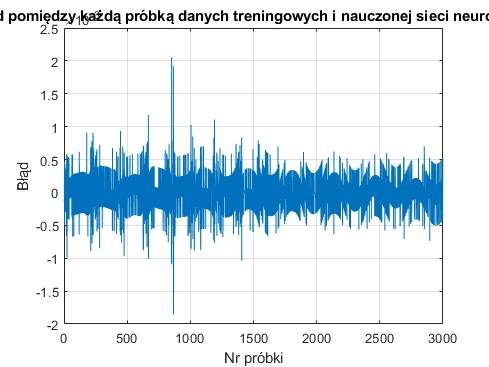


figure();
plot(Y_num - cell2mat(X_train(3:end)))
xlabel('Nr próbki')
ylabel('Błąd')
grid on
title('Błąd pomiędzy każdą próbką danych treningowych i nauczonej sieci neuronowej')

Aby przewidywać przyszłe próbki danych zamykamy pętlę sprzężenia zwrotnego wewnątrz naszej sieci:

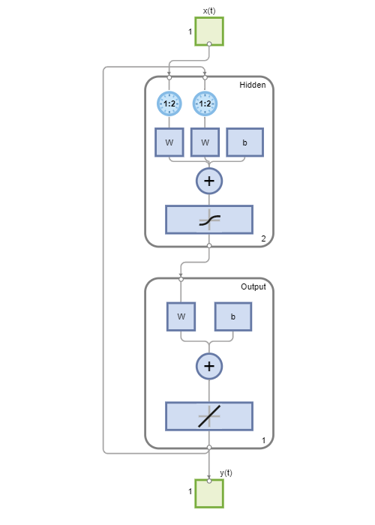

[netc,Xic,Aic] = closeloop(net,Xf,Af);
view(netc)

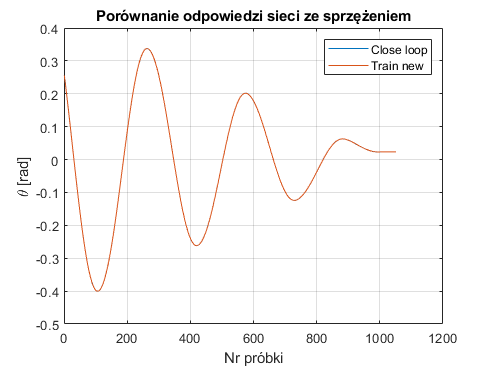



y2 = netc(Xnew,Xic,Aic);
yc_num = cell2mat(y2);
figure
plot(yc_num)
hold on 
plot(cell2mat(Xnew))
legend('Close loop', 'Train new')
xlabel('Nr próbki')
ylabel('\theta [rad]')
title('Porównanie odpowiedzi sieci ze sprzężeniem')
grid on
hold off

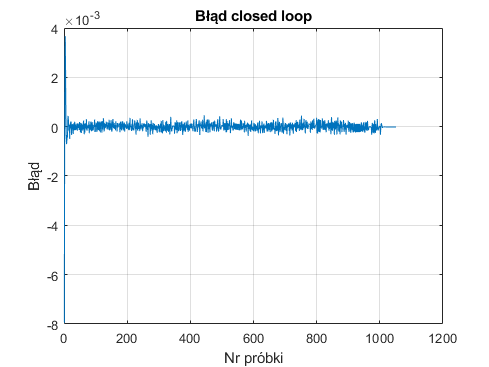


figure();
plot(yc_num - cell2mat(Xnew))
xlabel('Nr próbki')
ylabel('Błąd')
grid on
title('Błąd closed loop')

Model sieci neuronowej z zamkniętą pętlą sprzężenia zwrotnego działa bardzo dobrze. Warto zauważyć, że w pętli zamkniętej uzyskaliśmy mniejszy błąd niż w pętli otwartej pomimo nowych danych. Świadczy to o działaniu pętli sprzężenia zwrotnego i dobrze dobranych wag i biasów w naszej sieci.  

MODEL HYBRYDOWY DO TESTOWANIA:

Kolejnym krokiem była próba stworzenia hybrydowego modelu matematycznego naszego wahadła rekacyjnego, w którym współczynnik tarcia będzie wyznaczany na podstawie prędkości wahadła. Równanie ruchu wahadła w drganiach swobodnych mają poniższą postać:

Po zajęciach z laboratorium problemowego posiadamy macierz stanu naszego układu:

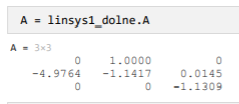

Jako parametr alfa przyjęliśmy przyjęliśmy wartość w komórce (2, 1) = -4.9764.

Współczynnik $\beta$ na laboratorium problemowym był równy:$\frac{\mathrm{\ }\mu_{\theta } \ x_2 }{J_{\theta } }$, więc $\beta =\frac{\mathrm{\ }\mu_{\theta } \ }{J_{\theta } }$. Moment bezwładności wahadła wyznaczony na Laboratorium Problemowym wynosił: $J_{\theta }$ = 0.0219. 

clear all
close all
load("doc\lab_3\narxnet_workspace.mat", 'dane_NN_test2')

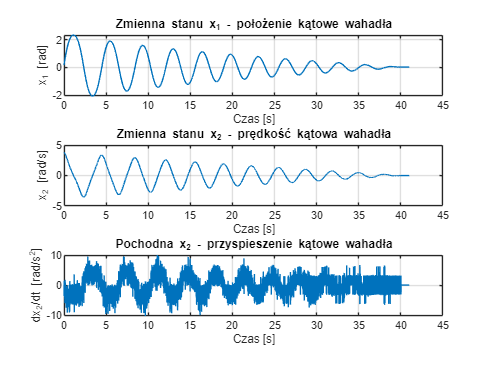

% x_begin_sample = 1152;
% x_end_sample = 1352;

x_begin_sample = 702;
x_end_sample = 4801;

time = dane_NN_test2.time(x_begin_sample:x_end_sample) - dane_NN_test2.time(x_begin_sample);
x_1 = dane_NN_test2.signals(1).values(x_begin_sample:x_end_sample);
x_1_prim = dane_NN_test2.signals(4).values(x_begin_sample:x_end_sample);
x_2_prim = [0; diff(dane_NN_test2.signals(4).values(x_begin_sample:x_end_sample))/0.01];

figure
subplot(3, 1, 1)
plot(time, x_1)
xlabel('Czas [s]')
ylabel('x_{1} [rad]')
title('Zmienna stanu x_{1} - położenie kątowe wahadła')
grid on
subplot(3, 1, 2)
plot(time, x_1_prim)
xlabel('Czas [s]')
ylabel('x_{2} [rad/s]')
title('Zmienna stanu x_{2} - prędkość kątowa wahadła')
grid on
subplot(3, 1, 3)
plot(time, x_2_prim)
xlabel('Czas [s]')
ylabel('dx_{2}/dt [rad/s^2]')
title('Pochodna x_{2} - przyspieszenie kątowe wahadła')
grid on

Prędkość kątowa wahadła w sterowniku wahadła reakcyjnego jest liczona jako zwykła pochodna numeryczna przez co pomiar ten jest mocno zaszumiony. Aby tego uniknąć przeprowadzamy filtrację jako średnią z 5 próbek.

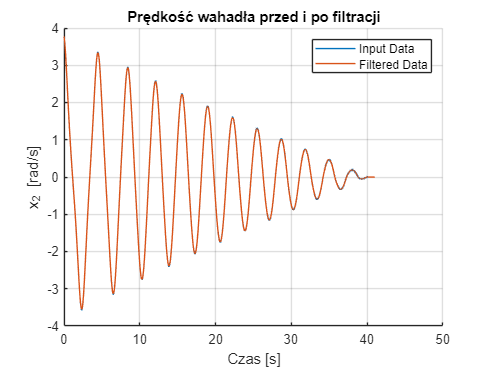

windowSize = 5; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

x_1_prim_filtered = filtfilt(b,a,x_1_prim);

figure
hold on
plot(time,x_1_prim)
plot(time,x_1_prim_filtered)
hold off
legend('Input Data','Filtered Data')
title('Prędkość wahadła przed i po filtracji')
xlabel('Czas [s]')
ylabel('x_{2} [rad/s]')
grid on

Następnie raz jeszcze obliczamy przyspieszenie kątowe jako pochodną przefiltrowanej prędkości po czasie próbkowania oraz ją filtrujemy:

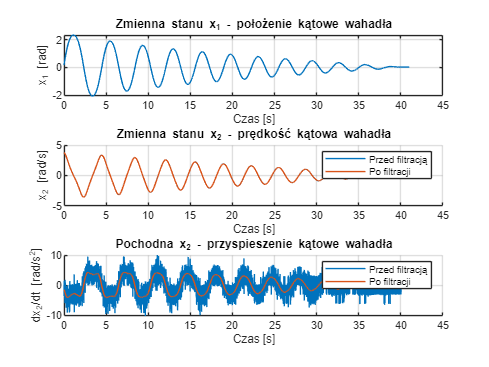

x_2_prim_filtered = [diff(x_1_prim_filtered)/0.01; x_2_prim(end)];
x_2_prim_filtered = filtfilt(b,a,x_2_prim_filtered);
figure
subplot(3, 1, 1)
plot(time, x_1)
xlabel('Czas [s]')
ylabel('x_{1} [rad]')
title('Zmienna stanu x_{1} - położenie kątowe wahadła')
grid on
subplot(3, 1, 2)
hold on
plot(time, x_1_prim)
plot(time,x_1_prim_filtered)
hold off
xlabel('Czas [s]')
ylabel('x_{2} [rad/s]')
title('Zmienna stanu x_{2} - prędkość kątowa wahadła')
legend('Przed filtracją', 'Po filtracji')
grid on
subplot(3, 1, 3)
hold on
plot(time, x_2_prim)
plot(time, x_2_prim_filtered)
xlabel('Czas [s]')
ylabel('dx_{2}/dt [rad/s^2]')
title('Pochodna x_{2} - przyspieszenie kątowe wahadła')
legend('Przed filtracją', 'Po filtracji')
grid on
hold off

Następnie obliczamy współczynnik $\mu_{\theta }$, który wynosi $\mu_{\theta } =\ \frac{\alpha x_1 -\ {\dot{x} }_2 }{x_2 }*\ J_{\theta }$

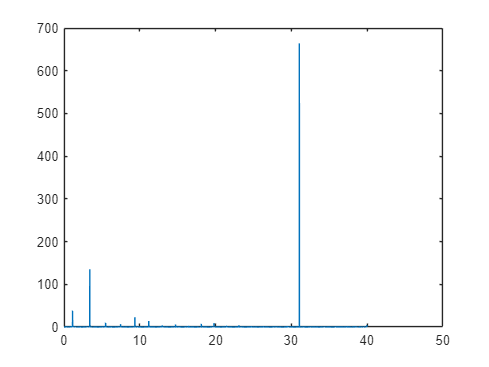

mi_theta = Beta_calculate(x_1, x_2_prim_filtered, x_1_prim_filtered);
figure
plot(time, mi_theta)

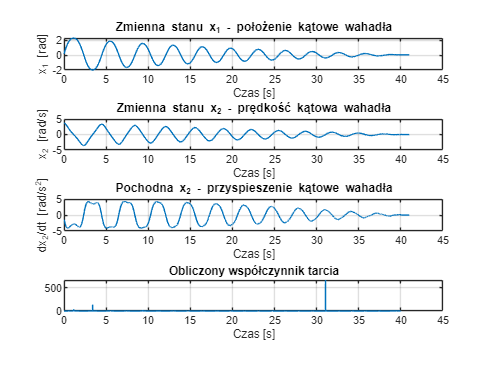

subplot(4, 1, 1)
plot(time, x_1)
xlabel('Czas [s]')
ylabel('x_{1} [rad]')
title('Zmienna stanu x_{1} - położenie kątowe wahadła')
grid on
subplot(4, 1, 2)
plot(time,x_1_prim_filtered)
xlabel('Czas [s]')
ylabel('x_{2} [rad/s]')
title('Zmienna stanu x_{2} - prędkość kątowa wahadła')
grid on
subplot(4, 1, 3)
plot(time, x_2_prim_filtered)
xlabel('Czas [s]')
ylabel('dx_{2}/dt [rad/s^2]')
title('Pochodna x_{2} - przyspieszenie kątowe wahadła')
grid on
subplot(4, 1, 4)
plot(time, mi_theta)
xlabel('Czas [s]')
title('Obliczony współczynnik tarcia')
grid on

Współczynnik tarcia w powyższym wykresie rośnie w okolicach górnego martwego położenia wahadła. Jest to spowodowane dążeniem prędkości wahadła do 0.  Z powyższych wykresu wykorzystamy część danych do nauczenia naszej sieci neuronowej.

Przygotowanie danych do nauki sieci:

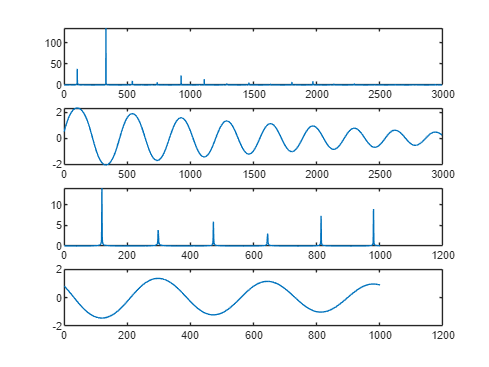

x_begin_sample = 10;
x_end_sample = 3000;
mi_theta_train = mi_theta(x_begin_sample:x_end_sample)';
x_1_train = [x_1(x_begin_sample:x_end_sample)'; x_1_prim_filtered(x_begin_sample:x_end_sample)'; x_2_prim_filtered(x_begin_sample:x_end_sample)'];


%%% Dane testowe
x_begin_sample = 1000;
x_end_sample = 2000;
mi_theta_test = mi_theta(x_begin_sample:x_end_sample)';
% x_1_test = x_1_prim_filtered(x_begin_sample:x_end_sample)';
x_1_test=[x_1(x_begin_sample:x_end_sample)'; x_1_prim_filtered(x_begin_sample:x_end_sample)'; x_2_prim_filtered(x_begin_sample:x_end_sample)'];



%%%%

mi_theta_train = tonndata(mi_theta_train,true,false);
network_inputs = tonndata(x_1_train,true,false);

mi_theta_test = tonndata(mi_theta_test,true,false);
close_loop_input = tonndata(x_1_test,true,false);

Przygotowanie parametrów sieci:

d1 = [1:2];
d2 = [1:2];
mi_net = narxnet(d1,d2,100, 'open');
mi_net.divideFcn = 'dividetrain';
mi_net.trainFcn = 'trainlm'

mi_net =

    Neural Network
 
              name: 'NARX Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 2
         numLayers: 2
        numOutputs: 1
    numInputDelays: 2
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 100
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      <a href="matlab:doc nnproperty.net_inputConnect">inputConnect<

mi_net.trainParam.epochs = 2500;
[Xs,Xi,Ai,Ts] = preparets(mi_net, network_inputs, {}, mi_theta_train);

Szkolenie sieci neruonowej:

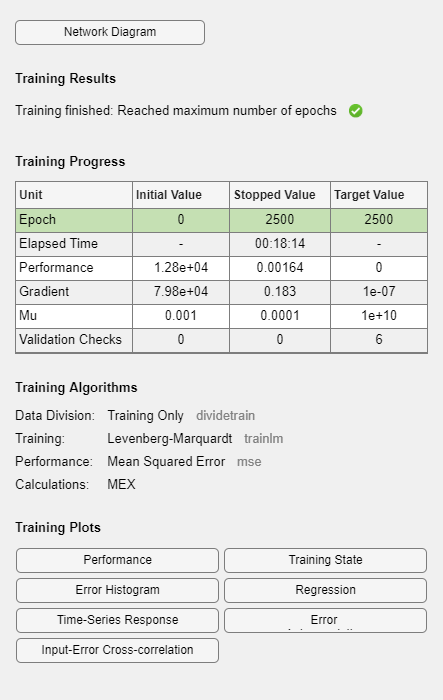

mi_net = train(mi_net,Xs,Ts,Xi,Ai);

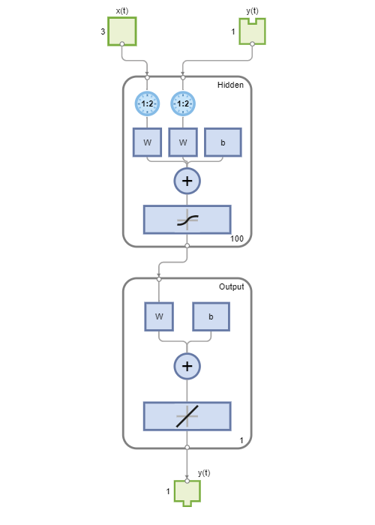

view(mi_net)

[Y,Xf,Af] = mi_net(Xs,Xi,Ai);
perf = perform(mi_net,Ts,Y)

perf = 0.0016

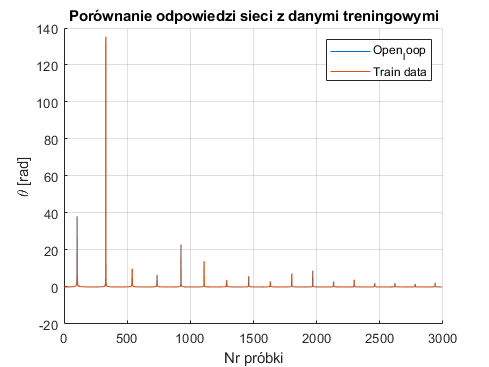

Y_num = cell2mat(Y);


figure();
hold on
plot(Y_num)
plot(cell2mat(mi_theta_train))
legend('Open_loop', 'Train data')
xlabel('Nr próbki')
ylabel('\theta [rad]')
title('Porównanie odpowiedzi sieci z danymi treningowymi')
grid on
hold off

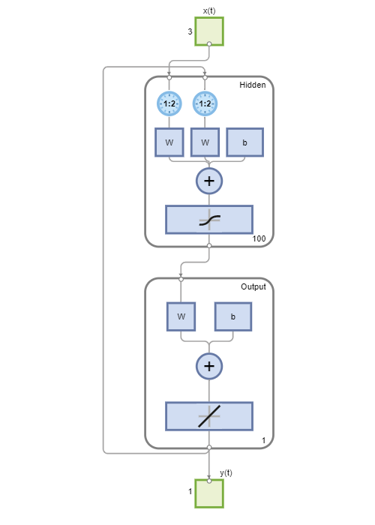



[netc,Xic,Aic] = closeloop(mi_net,Xf,Af);
view(netc)

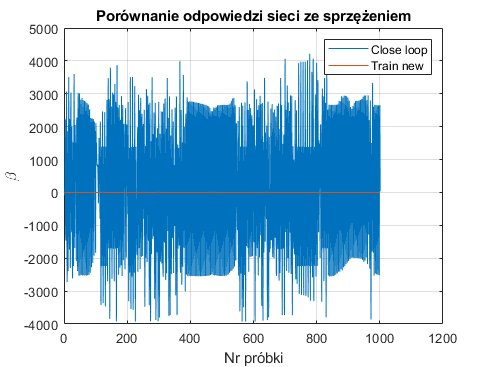


y2 = netc(close_loop_input,Xic,Aic);
yc_num = cell2mat(y2);

figure
plot(yc_num)
hold on 
plot(cell2mat(mi_theta_test))
legend('Close loop', 'Train new')
xlabel('Nr próbki')
ylabel('\beta')
title('Porównanie odpowiedzi sieci ze sprzężeniem')
grid on
hold off

Sieć w pętli otwartej działa bardzo dobrze. Niestety w pętli zamkniętej nie udało nam się przeprowadzić poprawnego szkolenia sieci. Przetestowane zostały wszystkie funkcje treningowe oraz różne kombinacje liczby warstw sieci i neuronów. 

function Beta_output = Beta_calculate(x_1, x_2_prim, x_2)
    alfa = -4.9764;
    Beta_output = (alfa .* x_1 - x_2_prim)./x_2;
    Beta_output = abs(Beta_output * 0.0219);
end
